### Luisa

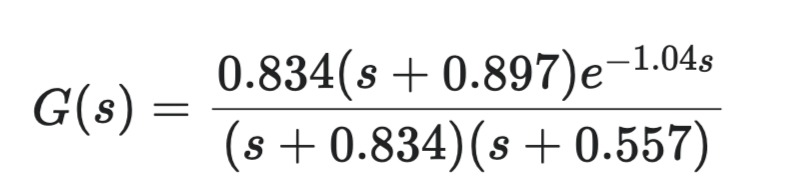

G = zpk(-0.897,[-0.834 -0.557],0.834,"InputDelay",1.04)

G =
 
                0.834 (s+0.897)
  exp(-1*s) * -------------------
              (s+0.834) (s+0.557)
 
Continuous-time zero/pole/gain model.



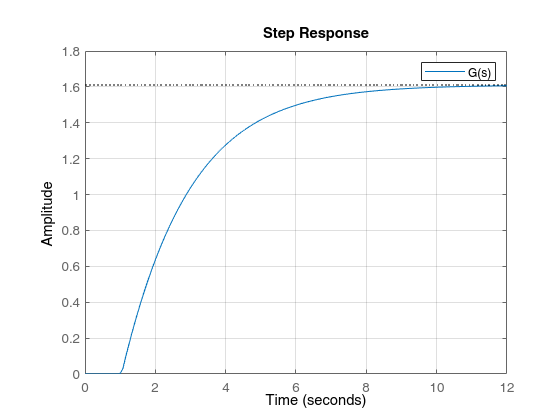

figure(1)
clf
step(G)
grid on
legend({'G(s)'})

[y,t]=step(G, 15);%recolectamos los datos tal y como los arroja matlab
inicio=find(y>0,01);%identificamos el dato a partir del cual el modelo responde a la entrada
yvals=y(inicio:end);%valores útiles de y
tvals=t(inicio:end);%valores útiles de t
k= 1.62; %valor de k según la fórmula dado que la entreda al inicio es 0

**Método de regresión**

[p,s]=polyfit(tvals,log(1-yvals/(k) + eps),1);%regresión lineal al logaritmo de y
T=-1/p(1); tau=p(2)/p(1); %valores de parámetros  T y tau según las fórmulas
tf_est=tf(k,[T 1],"InputDelay",tau)%función de transferencia resultante

tf_est =
 
                     1.62
  exp(-0.272*s) * -----------
                  2.608 s + 1
 
Continuous-time transfer function.



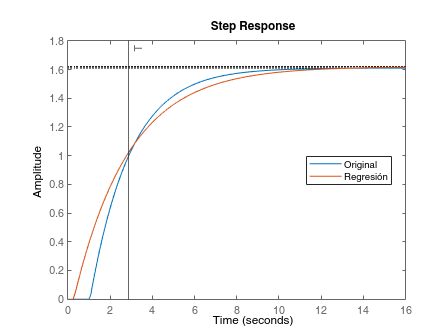

figure(1)
clf
step(G)
hold on
step(tf_est)
xline(T+tau,'-',{'T'})
legend({'Original','Regresión'},'Location','best')

### Miguel

G3 = tf([3.91],[1 7.71 12.7 8.76],'InputDelay',0.777)

G3 =
 
                               3.91
  exp(-0.777*s) * ------------------------------
                  s^3 + 7.71 s^2 + 12.7 s + 8.76
 
Continuous-time transfer function.



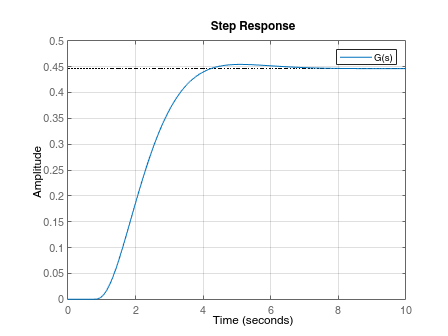

tiempofinal = 10;
figure(3)
clf
step(G3, tiempofinal)
grid on
legend({'G(s)'})

[y,t] = step(G3);%recolección de datos por recomendación de MatLab
inicio = find(y > 0,01);%dato a partir del cual el sistema reacciona
tau = t(inicio)%tiempo a partir del cual el sistema reacciona

tau = 0.8083

deltaY = y(end) - y(1)%delta de y por definición

deltaY = 0.4469

Mp = max(y) - y(end);%sobreimpulso máximo pode definición
Tp = t(y == max(y)) - tau;%tiempo de pico, se le debe restar el retardo
zeta = 1/sqrt(1+(pi/log(Mp/deltaY))^2)%valor de z (diapositivas)

zeta = 0.7939

%zeta = -log(Mp)/sqrt(pi^2+log(Mp)^2)%valor de z (Soderstrom)
omega0 = pi/(Tp*sqrt(1-zeta^2))%valor de omega0 por fórmulas

omega0 = 1.2072

tfEstimada=tf(deltaY*omega0^2,[1 2*zeta*omega0 omega0^2],'InputDelay',tau)%función de transferencia estimada

tfEstimada =
 
                         0.6513
  exp(-0.808*s) * ---------------------
                  s^2 + 1.917 s + 1.457
 
Continuous-time transfer function.



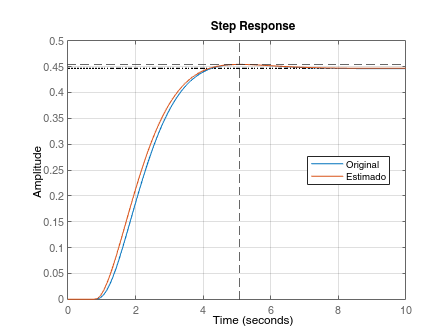

figure(3)
clf
step(G3,10)
hold on
step(tfEstimada,10)
grid on
xline(Tp+tau, '--')
yline(max(y),'--')

legend({'Original','Estimado'},'Location','best')

Punto 2

num= [0.834 0]

num =     0.8340         0


den = [1 57/500 -46979/200000]

den =     1.0000    0.1140   -0.2349


G = tf(num, den , 1)

G =
 
         0.834 z
  ----------------------
  z^2 + 0.114 z - 0.2349
 
Sample time: 1 seconds
Discrete-time transfer function.



L = 7; %longitud de la secuencia de ponderación
delay = length(den)-length(num);
Secuencia = ldiv(num,den,L-delay); %división larga
Secuencia = [zeros(1,delay) Secuencia]  %secuencia con retardo agregado

Secuencia =          0    0.8340   -0.0951    0.2067   -0.0459    0.0538   -0.0169


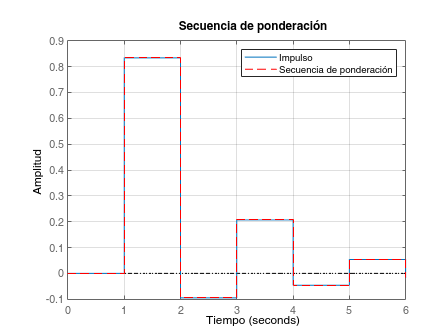

clf
impulse(G,0:1:L-1); %impulso
hold on
stairs(0:1:L-1, Secuencia,'r', 'LineStyle','--')
grid on
legend({'Impulso','Secuencia de ponderación'})
title("Secuencia de ponderación")
xlabel('Tiempo')
ylabel('Amplitud')